%% 7 blue_block, can, jello, marker, red_block, spatulas, yellow_block
imageFolder = sprintf("Data_and_Utilities/images/classification/")

imageFolder = "Data_and_Utilities/images/classification/"

imds = imageDatastore(imageFolder, LabelSource="foldernames", IncludeSubfolders=true);
tbl = countEachLabel(imds)

tbl = 7×2 table
       Label        Count
    ____________    _____

    blue_block       12  
    can              17  
    jello            17  
    marker           11  
    red_block        10  
    spatulas         10  
    yellow_block      8  


classNames = categories(imds.Labels)

classNames = 7×1 cell 数组
    {'blue_block'  }
    {'can'         }
    {'jello'       }
    {'marker'      }
    {'red_block'   }
    {'spatulas'    }
    {'yellow_block'}


numClasses = numel(classNames);1

ans = 1

[imdsTrain,imdsValidation,imdsTest] = splitEachLabel(imds,0.7,0.15,"randomized");

%% load : SqueezeNet
net = imagePretrainedNetwork(NumClasses=numClasses)

net =   dlnetwork - 属性:

         Layers: [68×1 nnet.cnn.layer.Layer]
    Connections: [75×2 table]
     Learnables: [52×3 table]
          State: [0×3 table]
     InputNames: {'data'}
    OutputNames: {'prob_flatten'}
    Initialized: 1

  使用 summary 查看摘要。


net = setLearnRateFactor(net,"conv10/Weights",10);
net = setLearnRateFactor(net,"conv10/Bias",10);
inputSize = net.Layers(1).InputSize

inputSize =    227   227     3


layers = net.Layers;
for i = 1:numel(layers)
    if isa(layers(i), 'nnet.cnn.layer.Convolution2DLayer')
        layers(i).WeightLearnRateFactor = 0; 
        layers(i).BiasLearnRateFactor = 0;   
    end
end

%% DataAugment
imageAugmenter = imageDataAugmenter( ...
    'RandRotation', [-45 45], ...
    'RandXReflection', true, ...
    'RandYReflection', true, ...
    'RandXTranslation', [-30 30], ...
    'RandYTranslation', [-30 30], ...
    'RandXScale', [0.8 1.2], ...
    'RandYScale', [0.8 1.2]);

augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    DataAugmentation=imageAugmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);

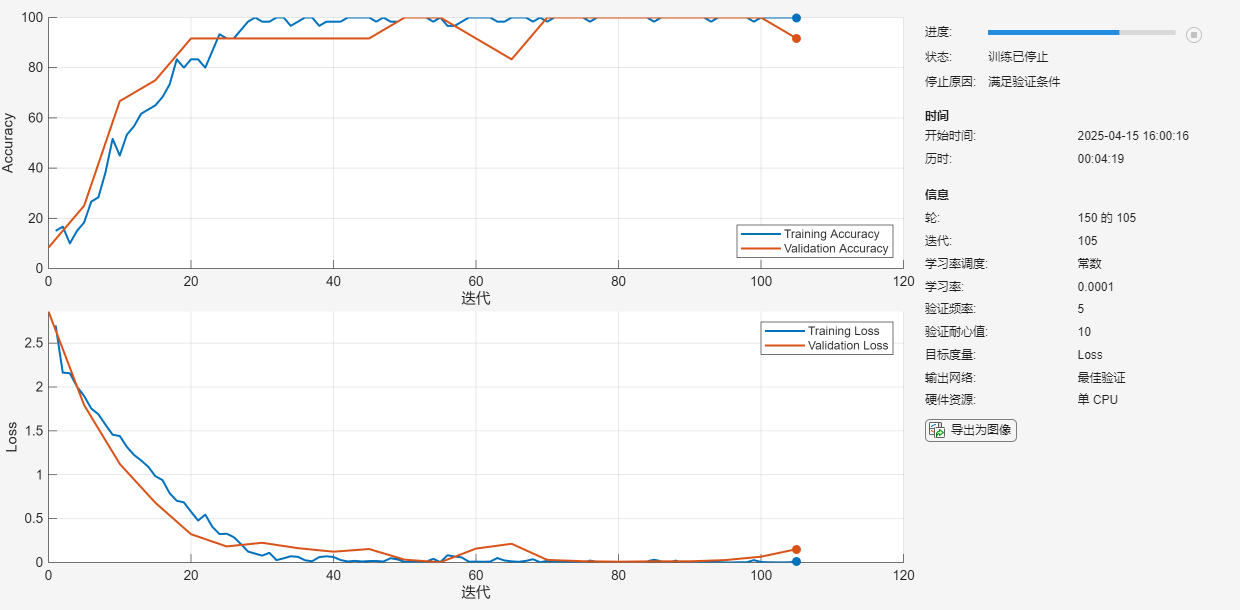

%% training
options = trainingOptions("adam", ...
    InitialLearnRate=1e-4, ...
    LearnRateDropFactor=0.5, ...
    LearnRateDropPeriod=10, ...
    ValidationData=augimdsValidation, ...
    ValidationFrequency=5, ...
    ValidationPatience=10, ... 
    MaxEpochs=150, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false, ...
    L2Regularization=1e-4);
net = trainnet(augimdsTrain,net,"crossentropy",options);

save('trainedModel.mat', 'net', 'classNames');

%% validation
accuracy = testnet(net,augimdsTest,"accuracy")

accuracy = 100

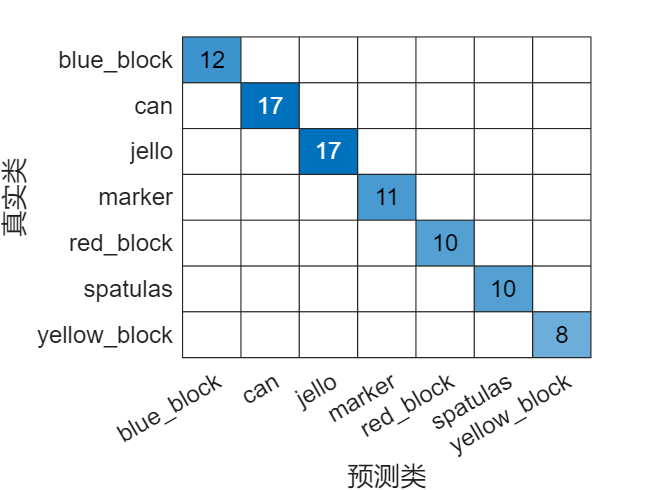


allScores = [];
labels = [];
misclassifiedFiles = {};
valImgs = imds;
for i = 1:numel(valImgs.Files)
    im = imread(valImgs.Files{i});
    im = imresize(im, inputSize(1:2));
    X = single(im);
    scores = predict(net,X);
    label = scores2label(scores,classNames);

    trueLabel = valImgs.Labels(i);
    if label ~= trueLabel
        misclassifiedFiles{end+1} = valImgs.Files{i}; 
    end
    labels = [labels; label];
    allScores = [allScores; scores];
end

figure
confusionchart(valImgs.Labels, labels);

disp('Misclassified image path：');

误分类图片路径：


for i = 1:numel(misclassifiedFiles)
    fprintf('[%d] %s\n', i, misclassifiedFiles{i});
end

%% predict
load('Data_and_Utilities/classification_model.mat');
inputSize = net.Layers(1).InputSize

inputSize =    227   227     3


im = imread('dataset/classification4/marker/cluster_34.png');
im = imresize(im, inputSize(1:2));
imwrite(im, sprintf('dataset/resize_%d.png',i+34));
X = single(im);
scores = predict(net,X)

scores = 1×7 single 行向量
    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000


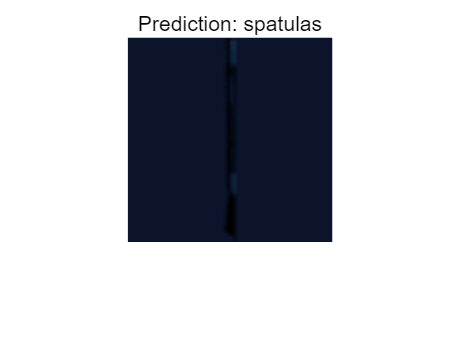

label = scores2label(scores,classNames);
figure
imshow(im)
title("Prediction: " + string(label))